# Control Lyapunov Functions

A Lyapunov function projects high dimensional dynamics onto a scalar positive definite function. Enforcing a condition on the time derivative of the Lyapunov function can guarantee convergence of the evolution of the full dynamics to a point or trajectory.


$$k_1\|x\|^2 \leq V(x) \leq k_2 \|x\|^2 \\
\dot{V}(x) \leq -k_3 \|x\|^2$$


enforces convergence of the system $\dot{x} = f(x)$ to the origin. An important fact about Lyapunov functions is that they are necessary and sufficent for systems which demonstrate convergence (there exists a Lyapunov function for every system which is locally expontentially stable). 

Control Lyapunov Functions (CLFs) extend this concept to control systems. For a control system

$\dot{x} = f(x) + g(x)u$ with $x \in E \subset \mathbb{R}^n$ and $u \in U \subset \mathbb{R}^m$, this system is only locally exponentially stable if and only if there exists a CLF $V: \mathbb{R}^n \rightarrow \mathbb{R}$ which satisfies


$$k_1\|x\|^2 \leq V(x) \leq k_2 \|x\|^2 \\
\inf_{u \in U} \dot{V}(x, u) = \inf_{u \in U} L_fV(x) + LgV(x)u \leq -\lambda V(x)$$


Given a CLF certifying the existence of stabilizing controllers, any locally Lipschitz controller $k(x)$ in the set


$$k(x) \in K(x) = \{u \in U \mid L_fV(x) + L_gV(x)u \leq -\lambda V(x)\}$$


will exponentially stabilize the system. 

Lyapunov functions can be synthesized for feedback linearizable systems. This process will be demonstrated on the pendulum and the cartpole.

clear; clc; close all;
addpath("../Models")
addpath("../Simulators/")
addpath("../QPs")

## CLF Synthesis for the Pendulum

Consider the pendulum dynamics and output


$$\left[ \matrix{\dot{\theta} \cr \ddot{\theta}}\right] = \left[\matrix{\dot{\theta} \cr -\frac{g}{L}\sin \theta} \right] + \left[\matrix{ 0 \cr \frac{1}{mL^2}} \right] \tau = f(x) + g(x)u \\
y(x) = \theta$$


As discussed in the feedback linearization script, applying the controller


$$\tau = mL^2\left(\frac{g}{L}\sin\theta -K_p y - K_d \dot{y}\right)$$


led to the output dynamics


$$\left[\matrix{\dot{y} \cr \ddot{y}}\right] = \left[ \matrix{0 & 1 \cr -K_p & -K_d}\right]\left[\matrix{y \cr \dot{y}}\right]$$


Which is a exponentially stable linear system. A Lyapunov function for the linear system of the form $V(\eta) = \eta^T P\eta$ can be synthesized by solving the Continuous Time Lyapunov Equation (CTLE) for a given $Q = Q^T \succ 0$:


$$A_{cl}^TP + PA_{cl} = -Q$$


$V$ is then a CLF on the output dynamics (since $u$ given by feedback linearization satisfies the inequality, and thus the infimum over $u$ will statisfy the inequality as well. 

F = [0 1; 0 0];
G = [0; 1];
Q = eye(2);
R = 1;
K = lqr(F, G, Q, R);

m = 1; g = 9.81; L = 0.5;
params.m = m; params.g = g; params.L = L;

A_cl = [0 1; -K];
P = lyap(A_cl', eye(2));
lambda = 1 / max(eig(P));

## Controller Synthesis via CLF

Several controllers can be synthesized from the CLF. Here, we present several controllers, including the min-norm controller, the Sontag Universal Controller, the u-CLF-QP, v-CLF-QP, and t-CLF-QP. Each of these are small variants on eachother, and are presented here. 

Consider the dynamics $\dot{x} = f(x) + g(x)u$. Assume outputs $y=h(x)$, and valid relative degree giving a normal form


$$\dot{\eta} = \hat{f}(\eta, z) + \hat{g}(\eta, z)u \\ \dot{z} = \omega(\eta, z)$$


We will assume a CLF on the outputs, $V_{\eta}(\eta)$. Recall however that $\eta$ is a function of $x$ via the diffeomorphism $\Phi : E \rightarrow Y \times Z$. Therefore, we can also define $V(x) = V_{\eta}(\eta(x))$. The min norm controller is:


$$k_{QP}(x) = \text{arg}\min_u \frac{1}{2}u^Tu \quad s.t. \quad L_fV(x) + L_gV(x)u \leq -\lambda V(x)$$


This is a quadratic program (QP), with a single inequality contraint, and has an explicit solution based on solving the KKT conditions. Let $a(x) = L_fV(x) + \lambda V(x)$ and $b^T(x) = L_gV(x)$. The explict solution is


$$k_{QP}(x) = \begin{cases} \frac{-a(x)b(x)}{b^T(x)b(x)} & a(x) > 0\\ 0 & a(x) \leq 0 \end{cases}$$


A somewhat similar in form controller is the Sontag Universal controller. This controller requires the small control property, and $u=0$ must stabilize the equilibrium.


$$k_{Son}(x) = \begin{cases} -\frac{a(x) + \sqrt{a(x)^2+(b^T(x)b(x))^2}}{b^T(x)b(x)}b(x) & b(x) \neq 0\\ 0 & b(x)=0 \end{cases}$$


While the min-norm CLF-QP is intuitive, it actually is not Lipschitz continuous. This is due to the fact that it lacks a feed-forward term. The Sontag controller is Lipschitz continuous. 

A natural extension of the min-norm controller, to regain Lipschitz continuity, is to solve for the minimum norm $v$, the auxiliary input used in feedback linearization. We take $u = \mathcal{G}(x)^+(-\mathcal{F}(x) + v)$. Recall that under this controller, the output dynamics are


$$\dot{\eta} = F\eta + Gv$$


Synthesizing the CLF from these linear output dynamics, we have $V(\eta) = \eta^TP\eta$. Therefore the v-CLF-QP can be written


$$k_{vQP}(x) = \text{arg}\min_u \frac{1}{2}v^Tv \quad s.t. \quad L_FV(\eta) + L_GV(\eta)u \leq -\lambda V(\eta)$$


Note that here $L_FV(\eta)$ and $L_GV(\eta)$ refer to Lie derivatives with respect to the linear output dynamics. They are thus easily computed:


$$L_FV(\eta) = \frac{\partial V}{\partial \eta} F\eta = \eta^T(F^TP + PF)\eta \\ L_GV(\eta) = \frac{\partial V}{\partial \eta} G = 2\eta^TPG$$


And so the optimization problem can be alternatively expressed


$$k_{vQP}(x) = \text{arg}\min_u \frac{1}{2}v^Tv \quad s.t. \quad \eta(x)^T(F^TP + PF)\eta(x)+ 2\eta^T(x)PGv \leq -\lambda \eta^T(x)P\eta(x)$$


This QP has a closed form solution as well


$$k_{vQP}(x) = \begin{cases} -\frac{1}{2} \frac{\eta(x)^T(F^TP + PF)\eta(x) + \lambda \eta(x)^TP\eta(x)}{\eta(x)^TPGG^TP\eta(x)}G^TP\eta(x) & \eta(x)^T(F^TP + PF)\eta(x) + \lambda \eta(x)^TP\eta(x) > 0\\ 0 & \eta(x)^T(F^TP + PF)\eta(x) + \lambda \eta(x)^TP\eta(x) \leq 0 \end{cases}$$


Since $u = \mathcal{G}(x)^+(-\mathcal{F}(x) + v)$, we can solve for $v$:


$$v = \mathcal{G}(x)u + \mathcal{F}(x)$$


This allows the v-CLF-QP to be reformulated to solve directly for $u$, as the u-CLF-QP:


$$k_{uQP}(x) = \text{arg}\min_u u^T\mathcal{G}(x)^T\mathcal{G}(x)u + 2\mathcal{F}(x)^T\mathcal{G}(x)u \quad s.t. \quad L_FV(x) + L_GV(x)(\mathcal{G}(x)u + \mathcal{F}(x) )\leq -\lambda V(x)$$


This QP also has an exact solution, which is precisely $u=\mathcal{G}(x)^+\left(-\mathcal{F}(x)+k_{vQP)(x)}\right)$, but can be alternately expressed:


$$k_{uQP}(x) = \begin{cases} (L_GV(x)\mathcal{G}(x))^+\left(-L_FV(x)-L_GV(x)\mathcal{F}(x)-\lambda V(x))& L_FV(x)+\lambda V(x)  > 0\\ -\mathcal{G}(x)^+\mathcal{F}(x) & L_FV(x)+\lambda V(x) \leq 0 \end{cases}$$


Finally, the t-CLF-QP incorporates tracking a trajectory which is depends on time instead of state. Performing the same technqiue as led to the u-CLF-QP, we get the t-CLF-QP:


$$k_{tQP}(x) = \text{arg}\min_u \|\mathcal{G}(x)u + \mathcal{F}(x)-y_d^{\gamma}(t)\|^2 \quad s.t. \quad L_FV(x ,t) + L_GV(x)(\mathcal{G}(x)u + \mathcal{F}(x) - y_d^{\gamma}(t)) \leq -\lambda V(x,t)$$


where $V(x,t) = e(x,t)^TPe(x,t)$ is now dependent on both time and state. 

And of course, the explicit version for this QP exists as well


$$k_{tQP}(x) = \begin{cases} (L_GV(x)\mathcal{G}(x))^+\left(-L_FV(x)-L_GV(x)(\mathcal{F}(x)-y_d^{\gamma}(t))-\lambda V(x)) & L_FV(x)+\lambda V(x)  > 0\\ -\mathcal{G}(x)^+(\mathcal{F}(x)-y_d^{\gamma}) & L_FV(x)+\lambda V(x) \leq 0 \end{cases}$$


Each of these controllers is implemented in the QP's folder of this repository. 

## CLF-QP Based Control for the Pendulum: Desired Position

First, we validate that each of the QP based controllers behaves the same as thier explicit counterparts. To do this, we will need to compute $L_fV(x)$, $L_gV(x)$, $L_FV(x)$, $L_GV(x)$, $\mathcal{F}(x)$, and $\mathcal{G}(x)$ and $V(x)$.


$$V(\eta) = \eta^TP\eta \\
L_fV(x) = \frac{\partial V}{\partial \eta} \frac{\partial \eta}{\partial x}f(x) = (2\eta(x)^TP)\frac{\partial \eta}{\partial x}f(x)\\
L_gV(x) = \frac{\partial V}{\partial \eta}\frac{\partial \eta}{\partial x}g(x) = 2\eta(x)^TP\frac{\partial \eta}{\partial x}g(x)\\
L_FV(\eta) = \frac{\partial V}{\partial \eta}F\eta = \eta^T(F^TP+PF)\eta \\
L_GV(\eta) = \frac{\partial V}{\partial \eta}G = 2\eta^TPG\\
\mathcal{F}(x) = L_f^2y = \frac{\partial}{\partial x} \left(L_fy \right)f(x) = \left[\matrix{0 & 1}\right] f(x)\\
\mathcal{G}(x) = L_gL_fy = \frac{\partial}{\partial x} \left(L_fy \right)g(x) = \left[\matrix{0 & 1}\right] g(x)$$


We will consider driving the pendulum to a static desired angle, $y = \theta - \theta_d$.  Note that $\frac{\partial \eta}{\partial x} = I$, simplifying calculations of $L_fV$ and $L_gV$.

thetaD =-3.1;
eta = @(x) [x(1, :) - thetaD; x(2, :)];
V = @(x) eta(x)' * P * eta(x);
LfV = @(x) 2 * eta(x)' * P * pendulum_f(x, params);
LgV = @(x) 2 * eta(x)' * P * pendulum_g(x, params);
LFV = @(x) eta(x)' * (F' * P + P * F) * eta(x);
LGV = @(x) 2*eta(x)' * P * G;
DLfy = [0 1];
calF = @(x) DLfy * pendulum_f(x, params);
calG = @(x) DLfy * pendulum_g(x, params);

Now, we implement and compare the controllers. First, lets set some initial conditions

theta0 =-0.6;
thetadot0 = -0.2;


t0 = 0; tf = 10;
x0 = [theta0; thetadot0];
xD = [thetaD; 0];

And now plug and chug.

% Feedback linearization for good luck
fdblin_ctrl = @(x) m*L^2 *(-g/L*sin(x(1, :)) -K*[x(1, :) - thetaD; x(2, :)]);

[t_fbl, x_fbl, u_fbl] = continuousSim(@pendulum, fdblin_ctrl, [t0, tf], x0, params);

% Minimum Norm Controller
min_norm_ctrl = @(x) kQP(lambda, V(x), LfV(x), LgV(x));
min_norm_ctrl_explicit = @(x) kQP_explicit(lambda, V(x), LfV(x), LgV(x));

[t_mn, x_mn, u_mn] = continuousSim(@pendulum, min_norm_ctrl, [t0, tf], x0, params);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

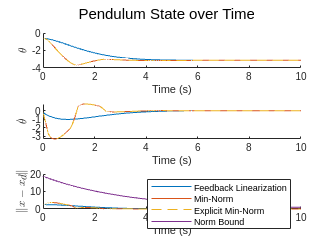

[t_mne, x_mne, u_mne] = continuousSim(...
    @pendulum, min_norm_ctrl_explicit, [t0, tf], x0, params);

% And plotting
figure;
subplot(3, 1, 1)
hold on;
plot(t_fbl, x_fbl(:, 1))
plot(t_mn, x_mn(:, 1))
plot(t_mne, x_mne(:, 1), '--')
xlabel('Time (s)')
ylabel('$\theta$', 'Interpreter', 'latex')
hold off
subplot(3, 1, 2)
hold on;
plot(t_fbl, x_fbl(:, 2))
plot(t_mn, x_mn(:, 2))
plot(t_mne, x_mne(:, 2), '--')
xlabel('Time (s)')
ylabel('$\dot{\theta}$', 'Interpreter', 'latex')
hold off
subplot(3, 1, 3)
hold on;
plot(t_fbl, vecnorm(x_fbl' - xD))
plot(t_mn, vecnorm(x_mn' - xD))
plot(t_mne, vecnorm(x_mne' - xD), '--')
plot(t_fbl, sqrt(max(eig(P)) / min(eig(P)))*exp(-1/(2*max(eig(P))) * t_fbl) * V(x0))
xlabel('Time (s)')
ylabel('$\|x - x_d\|$', 'Interpreter', 'latex')
legend({'Feedback Linearization', 'Min-Norm', 'Explicit Min-Norm', 'Norm Bound'})
hold off
sgtitle('Pendulum State over Time')

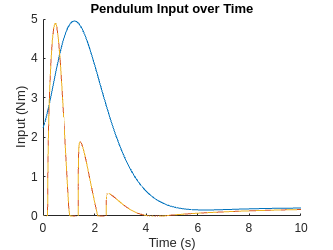


figure;
hold on;
plot(t_fbl, abs(u_fbl))
plot(t_mn, abs(u_mn))
plot(t_mne, abs(u_mne),  '--')
hold off;
xlabel('Time (s)')
ylabel('Input (Nm)')
title('Pendulum Input over Time')

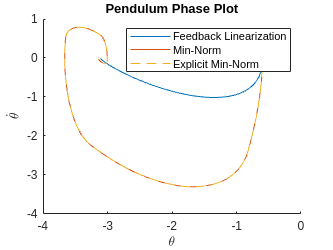


figure;
hold on;
plot(x_fbl(:, 1), x_fbl(:, 2))
plot(x_mn(:, 1), x_mn(:, 2))
plot(x_mne(:, 1), x_mne(:, 2),  '--')
hold off;
xlabel('$\theta$', 'Interpreter', 'latex')
ylabel('$\dot{\theta}$', 'Interpreter', 'latex')
legend({'Feedback Linearization', 'Min-Norm', 'Explicit Min-Norm'})
title('Pendulum Phase Plot')

Note, playing with the initial conditions, that the min norm QP uses less input than the feedback linearization does (note that in some cases, the plot of the QP input may be above the FBL, but this only occurs when the systems are in very different states (and thus different inputs are required to achieve the same rate of convergence). 

A piece of this analysis which was initially confusing to me was that the plot of the QP inputs is often higher than the FBL inputs (when plotted over time). In theory, at any given state, the QP should choose at most the actuation of feedback linearization. To check this, in the follow plot I plot *the action FBL would take at each state on the QP trajectory* against the QP input at that state. So the line is not physical for the FBL, as the input is not actually applied to the system. Instead, the plot allows a state-by-state comparison between FBL and QP inputs

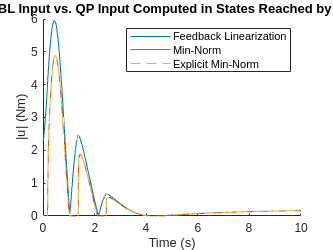

figure;
hold on;
fbl_QP_traj = abs(fdblin_ctrl(x_mn'));
plot(t_mn, fbl_QP_traj)
plot(t_mn, abs(u_mn))
plot(t_mne, abs(u_mne),  '--')
hold off;
xlabel('Time (s)')
ylabel('|u| (Nm)')
legend({'Feedback Linearization', 'Min-Norm', 'Explicit Min-Norm'})
title('FBL Input vs. QP Input Computed in States Reached by QP')

fprintf('QP <= FBL at all points: %s', mat2str(~any(fbl_QP_traj < u_mn)))

QP <= FBL at all points: true

E_fbl = trapz(t_fbl, abs(u_fbl));
E_mn = trapz(t_mn, abs(u_mn));
fprintf('Torque Consumed by Feedback Linearization: %0.2f', E_fbl)

Torque Consumed by Feedback Linearization: 13.36

fprintf('Torque Consumed by Minimum Norm Controller: %0.2f', E_mn)

Torque Consumed by Minimum Norm Controller: 4.47

Firstly, we do set that at every state, feedback linearization would infact choose the same or a larger input. However, note that for some initial conditions, feedback linearization actually consumes less torque than the min-norm controller. This is because the QP is only pointwise optimal; the FBL controller uses more torque at the start, which actually saves it energy later on. 

Next, consider the v-CLF-QP and u-CLF-QP (which are identical, with different formulations).

% v-CLF-QP
vCLFQP = @(x) calG(x) \ (-calF(x) + kvQP(eta(x), lambda, P, F, G));
vCLFQP_exp = @(x) calG(x) \ (-calF(x) + kvQP_explicit(eta(x), lambda, P, F, G));
uCLFQP = @(x) kuQP(lambda, calG(x), calF(x), LFV(x), LGV(x), V(x));
uCLFQP_exp = @(x) kuQP_explicit(lambda, calG(x), calF(x), LFV(x), LGV(x), V(x));

[t_v, x_v, u_v] = continuousSim(@pendulum, vCLFQP, [t0, tf], x0, params);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

[t_ve, x_ve, u_ve] = continuousSim(@pendulum, vCLFQP_exp, [t0, tf], x0, params);
[t_u, x_u, u_u] = continuousSim(@pendulum, uCLFQP, [t0, tf], x0, params);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

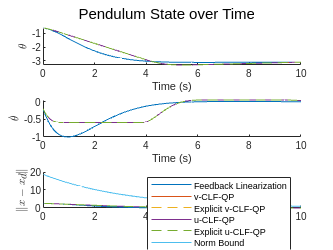

[t_ue, x_ue, u_ue] = continuousSim(@pendulum, uCLFQP_exp, [t0, tf], x0, params);

figure;
subplot(3, 1, 1)
hold on;
plot(t_fbl, x_fbl(:, 1))
plot(t_v, x_v(:, 1))
plot(t_ve, x_ve(:, 1), '--')
plot(t_u, x_u(:, 1))
plot(t_ue, x_ue(:, 1), '--')
xlabel('Time (s)')
ylabel('$\theta$', 'Interpreter', 'latex')

hold off
subplot(3, 1, 2)
hold on;
plot(t_fbl, x_fbl(:, 2))
plot(t_v, x_v(:, 2))
plot(t_ve, x_ve(:, 2), '--')
plot(t_u, x_u(:, 2))
plot(t_ue, x_ue(:, 2), '--')
xlabel('Time (s)')
ylabel('$\dot{\theta}$', 'Interpreter', 'latex')
hold off
subplot(3, 1, 3)
hold on;
plot(t_fbl, vecnorm(x_fbl' - xD))
plot(t_v, vecnorm(x_v' - xD))
plot(t_ve, vecnorm(x_ve' - xD), '--')
plot(t_u, vecnorm(x_u' - xD))
plot(t_ue, vecnorm(x_ue' - xD), '--')
plot(t_fbl, sqrt(max(eig(P)) / min(eig(P)))*exp(-1/(2*max(eig(P))) * t_fbl) * V(x0))
xlabel('Time (s)')
ylabel('$\|x - x_d\|$', 'Interpreter', 'latex')
legend({'Feedback Linearization', 'v-CLF-QP', 'Explicit v-CLF-QP', ...
    'u-CLF-QP', 'Explicit u-CLF-QP', 'Norm Bound'})
hold off
sgtitle('Pendulum State over Time')

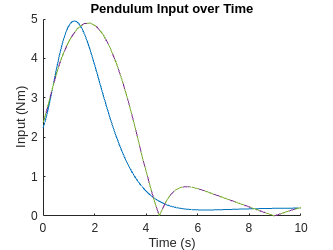


figure;
hold on;
plot(t_fbl, abs(u_fbl))
plot(t_v, abs(u_v))
plot(t_ve, abs(u_ve),  '--')
plot(t_u, abs(u_u))
plot(t_ue, abs(u_ue),  '--')
hold off;
xlabel('Time (s)')
ylabel('Input (Nm)')
title('Pendulum Input over Time')

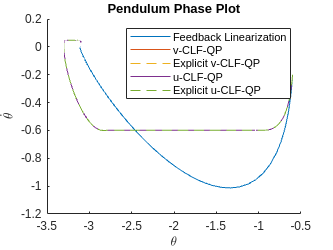


figure;
hold on;
plot(x_fbl(:, 1), x_fbl(:, 2))
plot(x_v(:, 1), x_v(:, 2))
plot(x_ve(:, 1), x_ve(:, 2),  '--')
plot(x_u(:, 1), x_u(:, 2))
plot(x_ue(:, 1), x_ue(:, 2),  '--')
hold off;
xlabel('$\theta$', 'Interpreter', 'latex')
ylabel('$\dot{\theta}$', 'Interpreter', 'latex')
legend({'Feedback Linearization', 'v-CLF-QP', 'Explicit v-CLF-QP', ...
    'u-CLF-QP', 'Explicit u-CLF-QP'})
title('Pendulum Phase Plot')

Again, in the follow plot I plot *the action FBL would take at each state on the QP trajectory* against the QP input at that state. So the line is not physical for the FBL, as the input is not actually applied to the system. Instead, the plot allows a state-by-state comparison between FBL and QP inputs

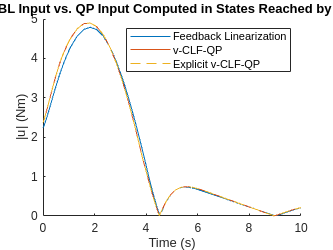

figure;
hold on;
fbl_QP_traj = abs(fdblin_ctrl(x_ve'));
plot(t_ve, fbl_QP_traj)
plot(t_v, abs(u_v))
plot(t_ve, abs(u_ve),  '--')
hold off;
xlabel('Time (s)')
ylabel('|u| (Nm)')
legend({'Feedback Linearization', 'v-CLF-QP', 'Explicit v-CLF-QP'})
title('FBL Input vs. QP Input Computed in States Reached by QP')

fprintf('QP <= FBL at all points: %s', mat2str(~any(fbl_QP_traj < u_ve)))

QP <= FBL at all points: false

E_fbl = trapz(t_fbl, abs(u_fbl));
E_ve = trapz(t_ve, abs(u_ve));
fprintf('Torque Consumed by Feedback Linearization: %0.2f', E_fbl)

Torque Consumed by Feedback Linearization: 13.36

fprintf('Torque Consumed by v-CLF-QP Controller: %0.2f', E_ve)

Torque Consumed by v-CLF-QP Controller: 17.30

*There are to be states where feedback linearization chooses a smaller input. *The QPs are minimizing the norm of $v$, not the norm of $u$. Take for instance a case where $v=0$ is returned by the optimization problem. If the control law $v=-K\eta$ in the feedback linearization moves in a way such that $\|\mathcal{G}(x)^+(-\mathcal{F}(x)-K\eta)\| <  \|-\mathcal{G}(x)^+\mathcal{F}(x)\|$, which is certainly possible, then the feedback linearization will choose a smaller normed input. The controller is actually enforcing minimum norm deviation from nonlinearity canceling torque. Additionally, note that the solution to the QP is very similar to the feedback linearizing controller anyway. However, note that for many initial conditions, feedback linearization actually uses more net torque than the min-norm controller. This is because the QP is only pointwise optimal; the FBL controller uses more torque at the start, which actually saves it torque later on. 

Lastly, examine the Sontag Universal Controller

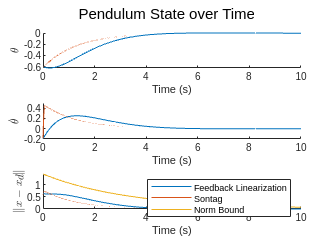

% Sontag Controller only works if k(0) = 0, so balance about upright
thetaD_son = 0;
xD_son = [thetaD_son; 0];
V_son = @(x) x' * P * x;
LfV_son = @(x) 2 * x' * P * pendulum_f(x, params);
LgV_son = @(x) 2 * x' * P * pendulum_g(x, params);
son_ctrl = @(x) kSon(lambda, V_son(x), LfV_son(x), LgV_son(x));

[t_s, x_s, u_s] = continuousSim(@pendulum, son_ctrl, [t0, tf], x0, params);
fdblin_ctrl_son = @(x) m*L^2 *(-g/L*sin(x(1, :)) -K*x);
[t_fbl_son, x_fbl_son, u_fbl_son] = continuousSim(...
    @pendulum, fdblin_ctrl_son, [t0, tf], x0, params);

% And plotting
figure;
subplot(3, 1, 1)
hold on;
plot(t_fbl_son, x_fbl_son(:, 1))
plot(t_s, x_s(:, 1))
xlabel('Time (s)')
ylabel('$\theta$', 'Interpreter', 'latex')

hold off
subplot(3, 1, 2)
hold on;
plot(t_fbl_son, x_fbl_son(:, 2))
plot(t_s, x_s(:, 2))
xlabel('Time (s)')
ylabel('$\dot{\theta}$', 'Interpreter', 'latex')
hold off
subplot(3, 1, 3)
hold on;
plot(t_fbl_son, vecnorm(x_fbl_son' - xD_son))
plot(t_s, vecnorm(x_s' - xD_son))
plot(t_fbl_son,...
    sqrt(max(eig(P)) / min(eig(P)))*exp(-1/(2*max(eig(P))) * t_fbl_son) * V_son(x0))
xlabel('Time (s)')
ylabel('$\|x - x_d\|$', 'Interpreter', 'latex')
legend({'Feedback Linearization', 'Sontag', 'Norm Bound'})
hold off
sgtitle('Pendulum State over Time')

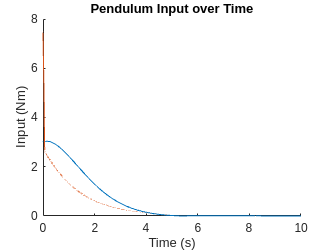


figure;
hold on;
plot(t_fbl_son, abs(u_fbl_son))
plot(t_s, abs(u_s))
hold off;
xlabel('Time (s)')
ylabel('Input (Nm)')
title('Pendulum Input over Time')

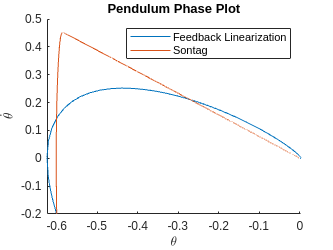


figure;
hold on;
plot(x_fbl_son(:, 1), x_fbl_son(:, 2))
plot(x_s(:, 1), x_s(:, 2))
hold off;
xlabel('$\theta$', 'Interpreter', 'latex')
ylabel('$\dot{\theta}$', 'Interpreter', 'latex')
legend({'Feedback Linearization', 'Sontag'})
title('Pendulum Phase Plot')

The Sontag controller does choose larger inputs than the FBL controller pointwise. Examining energy consumed:

E_fbl = trapz(t_fbl, abs(u_fbl));
E_s = trapz(t_s, abs(u_s));
fprintf('Energy Consumed by Feedback Linearization: %0.2f', E_fbl)

Energy Consumed by Feedback Linearization: 13.36

fprintf('Energy Consumed by Sontag Controller: %0.2f', E_s)

Energy Consumed by Sontag Controller: 3.85

The Sontag controller uses significantly less torque overall compared to the FBL controller. However, note that the Sontag controller only stabilizes systems which have the property that $k(0) = 0$, i.e. they have unforced equilibria. This controller thus requires pre-stabilization of the system in many cases to achieve this property. 

## CLF-QP Based Control for the Pendulum: Trajectory Tracking

We now turn to a perhaps more useful concept of trajectory tracking. There are two primary methods of tracking trajectories: first, the trajectory can be defined as a function of time, $y=y_a(x) - y_d(t)$, or the trajectory can be parameterized by a 'phase variable', which is a function of state, $y = y_a(x) - y_d(\tau(x))$. Time-based trajectories require the t-CLF-QP, while any of the above mentioned QPs will deal with the phase variable parameterization. 

First, we will analyze the time-based trajectory. Construct the feedback linearization and t-CLF-QP controllers for comparison

err = @(x, t) [x(1, :) - sin(t); x(2, :) - cos(t)];
V_t = @(x, t) err(x, t)' * P * err(x, t);
LFV_t = @(x, t) err(x, t)' * (F' * P + P * F) * err(x, t);
LGV_t = @(x, t) 2*err(x, t)' * P * G;

fdblin_traj = @(x, t) ...
    m*L^2*(-g/L*sin(x(1, :)) - sin(t) - K * [x(1, :) - sin(t); x(2, :) - cos(t)]);
tCLFQP = @(x, t) ktQP(...
    lambda, -sin(t), calG(x), calF(x), LFV_t(x, t), LGV_t(x, t), V_t(x, t));
tCLFQP_exp = @(x, t) ktQP_explicit(...
    lambda, -sin(t), calG(x), calF(x), LFV_t(x, t), LGV_t(x, t), V_t(x, t));

[t_tfbl, x_tfbl, u_tfbl] = continuousSim(@pendulum, fdblin_traj, [t0, tf], x0, params);
[t_t, x_t, u_t] = continuousSim(@pendulum, tCLFQP, [t0, tf], x0, params);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

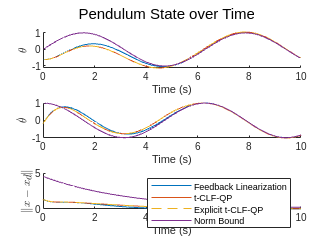

[t_te, x_te, u_te] = continuousSim(@pendulum, tCLFQP_exp, [t0, tf], x0, params);


% And plotting
figure;
subplot(3, 1, 1)
hold on;
plot(t_tfbl, x_tfbl(:, 1))
plot(t_t, x_t(:, 1))
plot(t_te, x_te(:, 1), '--')
plot(t_t, sin(t_t))
xlabel('Time (s)')
ylabel('$\theta$', 'Interpreter', 'latex')
hold off
subplot(3, 1, 2)
hold on;
plot(t_tfbl, x_tfbl(:, 2))
plot(t_t, x_t(:, 2))
plot(t_te, x_te(:, 2), '--')
plot(t_t, cos(t_t))
xlabel('Time (s)')
ylabel('$\dot{\theta}$', 'Interpreter', 'latex')
hold off
subplot(3, 1, 3)
hold on;
plot(t_tfbl, vecnorm(x_tfbl' - [1; 0] .* sin(t_tfbl)' - [0; 1] * cos(t_tfbl)'))
plot(t_t, vecnorm(x_t' - [1; 0] .* sin(t_t)' - [0; 1] * cos(t_t)'))
plot(t_te, vecnorm(x_te' - [1; 0] .* sin(t_te)' - [0; 1] * cos(t_te)'), '--')
plot(t_t, ...
    sqrt(max(eig(P)) / min(eig(P)))*exp(-1/(2*max(eig(P))) * t_t) * V_t(x0, 0))
xlabel('Time (s)')
ylabel('$\|x - x_d\|$', 'Interpreter', 'latex')
legend({'Feedback Linearization', 't-CLF-QP', 'Explicit t-CLF-QP', 'Norm Bound'})
hold off
sgtitle('Pendulum State over Time')

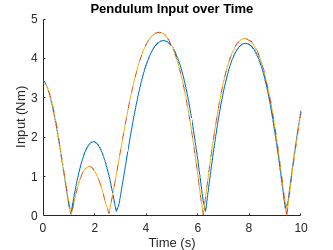


figure;
hold on;
plot(t_tfbl, abs(u_tfbl))
plot(t_t, abs(u_t))
plot(t_te, abs(u_te),  '--')
hold off;
xlabel('Time (s)')
ylabel('Input (Nm)')
title('Pendulum Input over Time')

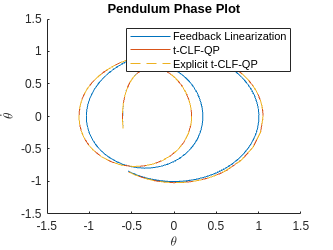


figure;
hold on;
plot(x_tfbl(:, 1), x_tfbl(:, 2))
plot(x_t(:, 1), x_t(:, 2))
plot(x_te(:, 1), x_te(:, 2),  '--')
hold off;
xlabel('$\theta$', 'Interpreter', 'latex')
ylabel('$\dot{\theta}$', 'Interpreter', 'latex')
legend({'Feedback Linearization', 't-CLF-QP', 'Explicit t-CLF-QP'})
title('Pendulum Phase Plot')

Things behave about as expected (having made it this far). The t-CLF-QP and feedback linearization behave qualitatively similarly, and both result in exponential convergence to the trajectory. We can of course look at torque usage

E_tfbl = trapz(t_tfbl, abs(u_tfbl));
E_t = trapz(t_t, abs(u_t));
fprintf('Energy Consumed by Feedback Linearization: %0.2f', E_tfbl)

Energy Consumed by Feedback Linearization: 24.62

fprintf('Energy Consumed by t-CLF-QP Controller: %0.2f', E_t)

Energy Consumed by t-CLF-QP Controller: 25.27

In line with other experiments, the t-CLF-QP uses more energy than the feedback linearization does in aggregate. 

Moving on to the phase-based tracking, I need to come up with a good output to track. Probably want it to be relative degree 2, so it can only depend on $\theta$. 